# **TU: Time-Domain Statistical Features**

Industrial AI & Automation by Y.K.Kim

Mod: 2024-2

## Introduction

Extract Time-Domain Features of a Simple Sinewave

## Include path

addpath('Library')  

## Dataset

### Generate Signals

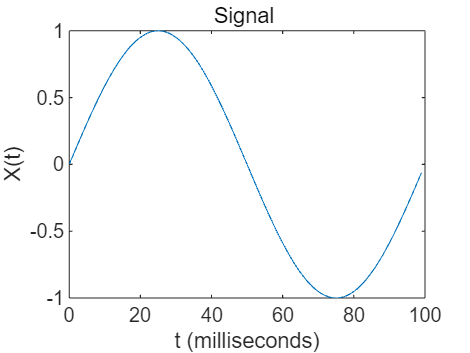

close all
clear 

Fs = 1000;            % Sampling frequency                    
T = 1/Fs;             % Sampling period       
N = 100;             % Length of signal
t = (0:N-1)*T;        % Time vector


% Information Signal 
fa=10;      % 10Hz signal
fa2=55;    % 55Hz signal
X = 0.0 + 1 * sin(2.0*pi*fa*t)+0*sin(2.0*pi*fa2*t); 

% Plot signals
figure()
plot(1000*t,X)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('X(t)')

### Mix Signal with Noise

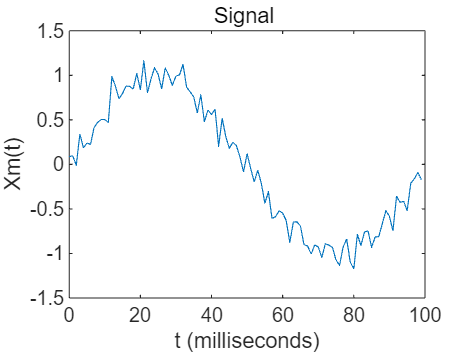


% Noise
noise=0.1*randn(size(t));

% Mixed Signal
Xn = 1 * sin(2.0*pi*fa*t)+noise; 


% Plot signals
figure()
plot(1000*t,Xn)
title('Signal ')
xlabel('t (milliseconds)')
ylabel('Xm(t)')

## Exercise:  Time-Domain Features  

Obtain the following features in time domain. Compare your code with MATLAB functions

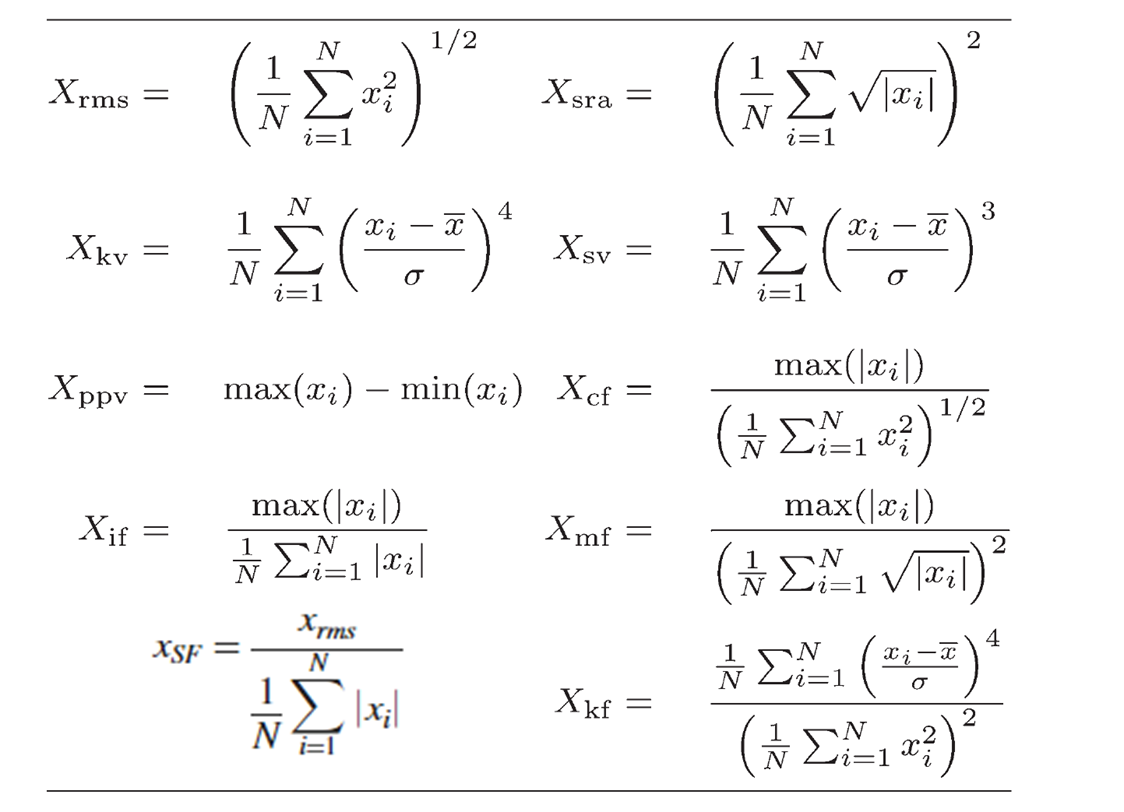

% x:        Input data
% xfeature: Table for feature of x

x=Xn;        % x=X % without noise
xfeature = table;
N=length(x);


%% mean and STD
xfeature.mean=mean(x);
xfeature.std=std(x);

%% RMS
xfeature.rms = sqrt(mean(x.^2));
%% Square Root Average
xfeature.sra = (mean(sqrt(abs(x))))^2;

%% Average of Absolute Value
xfeature.aav=sum(abs(x))/N;



%% Energy (sum of power_2)
xfeature.energy=sum(x.^2);


%% Peak
xfeature.peak = max(abs(x));

%% Peak2Peak
xfeature.ppv=peak2peak(x);


%% Impulse Factor
xfeature.if=xfeature.peak/xfeature.aav;

%% Shape Factor
xfeature.sf=xfeature.rms/xfeature.aav;

%% Crest Factor
xfeature.crest = xfeature.peak / xfeature.rms;

% Marginal(Clearance) Factor
xfeature.mf=xfeature.peak/xfeature.sra;

%% Skewness
xfeature.sk=skewness(x);


%% Kurtosis
xfeature.kt=kurtosis(x);


% Print all features
xfeature

xfeature = 1×14 table
      mean        std        rms        sra       aav      energy     peak      ppv        if        sf      crest       mf         sk         kt  
    ________    _______    _______    _______    ______    ______    ______    ______    ______    ______    ______    ______    ________    ______

    -0.01085    0.71816    0.71464    0.58004    0.6372    51.071    1.1719    2.3362    1.8391    1.1215    1.6398    2.0203    0.040511    1.5879


## Exercise 2

Compare the time-domain features of signals with and without noise added.

% 1️⃣ Clean signal
x = X;
xfeature_clean = table;
N = length(x);
xfeature_clean.mean   = mean(x);
xfeature_clean.std    = std(x);
xfeature_clean.rms    = sqrt(mean(x.^2));
xfeature_clean.sra    = (mean(sqrt(abs(x))))^2;
xfeature_clean.aav    = sum(abs(x))/N;
xfeature_clean.energy = sum(x.^2);
xfeature_clean.peak   = max(abs(x));
xfeature_clean.ppv    = peak2peak(x);
xfeature_clean.if     = xfeature_clean.peak/xfeature_clean.aav;
xfeature_clean.sf     = xfeature_clean.rms/xfeature_clean.aav;
xfeature_clean.crest  = xfeature_clean.peak/xfeature_clean.rms;
xfeature_clean.mf     = xfeature_clean.peak/xfeature_clean.sra;
xfeature_clean.sk     = skewness(x);
xfeature_clean.kt     = kurtosis(x);

% 2️⃣ Noisy signal
x = Xn;
xfeature_noisy = table;
N = length(x);
xfeature_noisy.mean   = mean(x);
xfeature_noisy.std    = std(x);
xfeature_noisy.rms    = sqrt(mean(x.^2));
xfeature_noisy.sra    = (mean(sqrt(abs(x))))^2;
xfeature_noisy.aav    = sum(abs(x))/N;
xfeature_noisy.energy = sum(x.^2);
xfeature_noisy.peak   = max(abs(x));
xfeature_noisy.ppv    = peak2peak(x);
xfeature_noisy.if     = xfeature_noisy.peak/xfeature_noisy.aav;
xfeature_noisy.sf     = xfeature_noisy.rms/xfeature_noisy.aav;
xfeature_noisy.crest  = xfeature_noisy.peak/xfeature_noisy.rms;
xfeature_noisy.mf     = xfeature_noisy.peak/xfeature_noisy.sra;
xfeature_noisy.sk     = skewness(x);
xfeature_noisy.kt     = kurtosis(x);

% 3️⃣ Compare
disp('--- Clean Signal Features ---')

--- Clean Signal Features ---


disp(xfeature_clean)

       mean         std        rms        sra        aav      energy    peak    ppv      if        sf      crest       mf          sk         kt 
    __________    _______    _______    _______    _______    ______    ____    ___    ______    ______    ______    ______    ___________    ___

    3.0947e-17    0.71067    0.70711    0.57863    0.63641      50       1       2     1.5713    1.1111    1.4142    1.7282    -1.2381e-16    1.5



disp('--- Noisy Signal Features ---')

--- Noisy Signal Features ---


disp(xfeature_noisy)

      mean        std        rms        sra       aav      energy     peak      ppv        if        sf      crest       mf         sk         kt  
    ________    _______    _______    _______    ______    ______    ______    ______    ______    ______    ______    ______    ________    ______

    -0.01085    0.71816    0.71464    0.58004    0.6372    51.071    1.1719    2.3362    1.8391    1.1215    1.6398    2.0203    0.040511    1.5879



## Exercise 3

Create a module, named as  `timeFeatures.m`  that returns time-domain features in table form.

Save it in `\IAIA\Library\` folder

See [**timeFeatures_student.m**](https://github.com/ykkimhgu/HGU_IAIA/tree/main/Library) as an example.

Example: 

xfeature=timeFeatures(x)

xfeature = 1×14 table
      mean        std        rms        sra       aav      energy     peak      ppv        if        sf      crest       mf         sk         kt  
    ________    _______    _______    _______    ______    ______    ______    ______    ______    ______    ______    ______    ________    ______

    -0.01085    0.71816    0.71464    0.58004    0.6372    51.071    1.1719    2.3362    1.8391    1.1215    1.6398    2.0203    0.040511    1.5879
